# Proyecto Final

Obtiene todas las imágenes de cada clase del directorio *Objetos_segmentados*

[imageClasses,labelMap] = ImageProcessing.getImagesClasses("Objetos_segmentados");

Se muestra la imagen 3 de la segunda clase

imshow(imageClasses{2}{3})

Se muestran las propiedades de labelMap y un ejemplo de su uso

labelMap
fprintf('A la clase %d le pertence la etiqueta %s',1,labelMap(1));

Divide a las imágenes en datos de entreneamiento y datos de prueba

images_train = cellfun(@(imageClass) imageClass(1:15), imageClasses, 'UniformOutput', false);
images_test = cellfun(@(imageClass) imageClass(16:end), imageClasses, 'UniformOutput', false);

Para cada clase de imagenes se obtiene su cuantizador vectorial

sizeQuantizer = 8; % Tamaño de los cuantizadores vectoriales
vecQuantizers = {}; % Cell array para almacenar a los cuantizadores vectoriales
for i = 1:length(images_train)
  pixels = ImageProcessing.imgClass2matrix(images_train{i});
  C1 = 1/length(pixels) *sum(pixels);
  [idx, C] = CuantizadorVectorial.LindeBuzoGray(C1,sizeQuantizer,double(pixels));
  vecQuantizers{i} = {idx, C};
end

Se verifican los centroides obtenidos, así como la cantidad de elementos que contiene cada grupo en el cuantizador vectorial de la clase appleJuice.

idx_1 = vecQuantizers{1}{1}; %Índices asignados a cada pixel de la clase appleJuice
C_1 = vecQuantizers{1}{2} %Centroides del cuantizador de la clase appleJuice
for i=1:sizeQuantizer
  fprintf('Centroide: %d  Elementos: %d\n',i,numel(find(idx_1 == i)))
end

Clasificación de las imagenes de entrenamiento

disp('Clasificando las imágenes de entrenamiento')

Clasificando las imágenes de entrenamiento


La clasificación para las imágenes de la clase 1 (appleJuice) fue:
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

La clasificación para las imágenes de la clase 2 (blueBowl) fue:
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2

La clasificación para las imágenes de la clase 3 (blueLego) fue:
     3     3     3     3     3     3     3     3     3     2     3     3     3     3     3

La clasificación para las imágenes de la clase 4 (blueMug) fue:
     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4

La clasificación para las imágenes de la clase 5 (blueSpoon) fue:
     5     5     2     2     2     2     2     5     5     5     5     5     5     5     5

La clasificación para las imágenes de la clase 6 (chocolateCookies) fue:
     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6

La clasificación para las imágenes de la clase 7

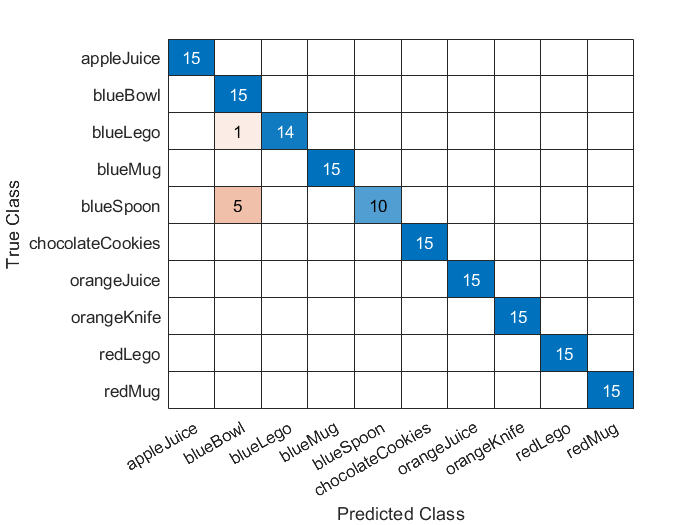

clasificacionCuantVect(images_train,vecQuantizers,labelMap)

Clasificación de las imagenes de prueba

disp('Clasificando las imágenes de prueba')

Clasificando las imágenes de prueba


La clasificación para las imágenes de la clase 1 (appleJuice) fue:
     1     1     1     1     1

La clasificación para las imágenes de la clase 2 (blueBowl) fue:
     2     2     2     2     2

La clasificación para las imágenes de la clase 3 (blueLego) fue:
     3     3     3     2     3

La clasificación para las imágenes de la clase 4 (blueMug) fue:
     4     4     4     4     4

La clasificación para las imágenes de la clase 5 (blueSpoon) fue:
     5     5     5     3     5

La clasificación para las imágenes de la clase 6 (chocolateCookies) fue:
     6     6     6     6     6

La clasificación para las imágenes de la clase 7 (orangeJuice) fue:
     7     7     7     7     7

La clasificación para las imágenes de la clase 8 (orangeKnife) fue:
     8     8     8     8     8

La clasificación para las imágenes de la clase 9 (redLego) fue:
     9     9     9     9     9

La clasificación para las imágenes de la clase 10 (redMug) fue:
    10    10    10    10    10



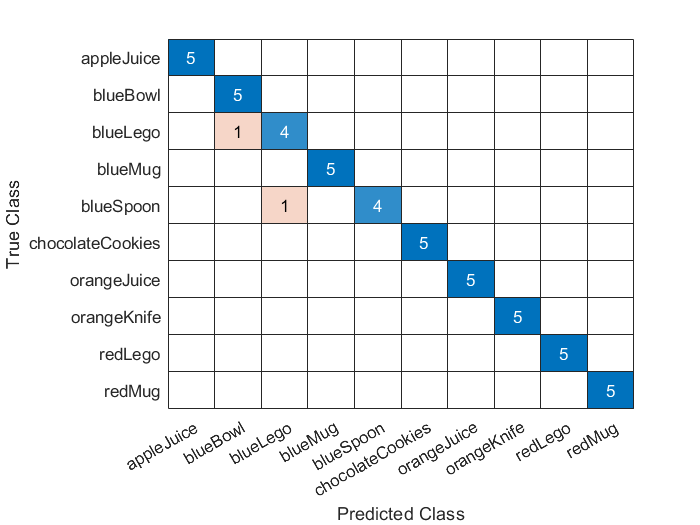

clasificacionCuantVect(images_test,vecQuantizers,labelMap)

**Clasificación de imágenes mediante cuantización vectorial**

Función para clasificar las imagenes, ya sea de entrenamiento o de prueba mediante la tecnica de cuantización vectorial.

Al final muestra su matriz de confusión.

function clasificacionCuantVect(imgClass,quantizers,labelMap)
  prediction = double.empty; % Valores que el clasificador predice
  actual = double.empty; % Valores reales
  for i=1:length(imgClass) % Itera sobre las clases
    nImgs = length(imgClass{i});
    clasifications = zeros(1,nImgs);
    for j=1:nImgs % Itera sobre las imágenes de la clase iésima
      % Obtiene los pixeles de la imagen
      pixels = ImageProcessing.img2matrix(imgClass{i}{j});
      % Obtiene la clasificación de la imagen de acuerdo a su distancia
      % mínima a cada cuantizador
      clasifications(j) = CuantizadorVectorial.clasificador(double(pixels),quantizers);
    end
    prediction = [prediction,clasifications];
    actual = [actual,ones(1,nImgs)*i];
    fprintf('La clasificación para las imágenes de la clase %d (%s) fue:\n',i,labelMap(i));
    disp(clasifications)
  end
  % Obtiene las etiquetas de los valores reales y predichos
  labelActual = arrayfun(@(num) labelMap(num),actual,'UniformOutput',false);
  labelPred = arrayfun(@(num) labelMap(num),prediction,'UniformOutput',false);
  % Genera una matriz de confusión y las muestra
  confusionchart(labelActual,labelPred)
end